# 基于压缩感知的TV滤波器降噪

作者: 何一林 ilin12, LPS of ECNU

Email: yilinoptics@outlook.com

时间: 2020/11/03

# Matlab 实时脚本mlx

    实时脚本是在一个称为实时编辑器的交互式环境中同时包含代码、输出和格式化文本的程序文件。在实时脚本中，您可以编写代码并查看生成的输出和图形以及相应的源代码。添加格式化文本、图像、超链接和方程，以创建可与其他人共享的交互式记叙脚本。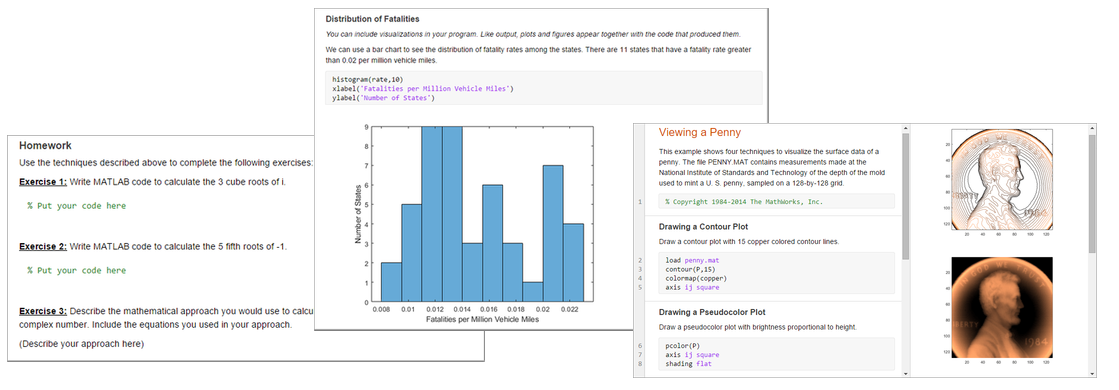

详细可在help浏览器中搜索实时脚本[help](https://ww2.mathworks.cn/help/matlab/live-scripts-and-functions.html?s_tid=srchtitle)

# 图像操作

    我们在图像处理过程中主要使用矩阵的方法来对图像进行操作时，通常有两种操作方式：    一，将图像进行向量化，然后按照线性代数中描述的矩阵操作方式来进行操作；二，通过对图像进行二维卷积或者三维卷积方式进行操作。

#### 原图

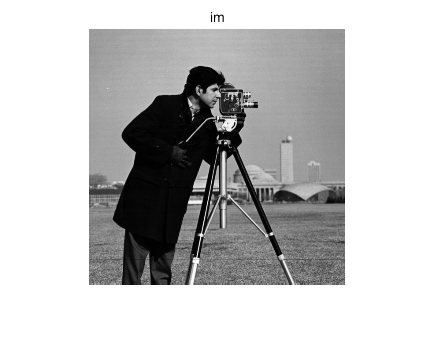

im = double(imread('cameraman.tif'));
imshow(im, []);
title('im');

size(im)

ans =    256   256


#### 二值编码

rand(4,4)

ans =     0.9533    0.6645    0.1639    0.0439
    0.6355    0.8571    0.2277    0.0920
    0.1768    0.7407    0.4235    0.7317
    0.7237    0.0958    0.9729    0.9744


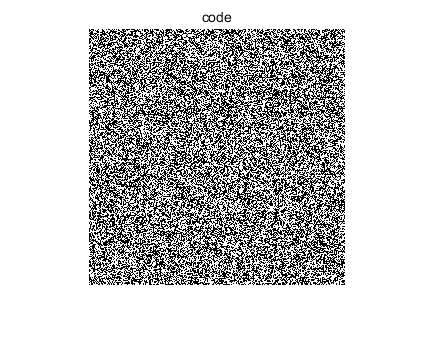

code = rand(size(im));
thold = 0.5;
code(code<thold) = 0;
code(code>=thold) = 1;
imshow(code, []);
title('code');

[height, width] = size(code)

height = 256

width = 256

## 矩阵操作

### 图像向量化

var_im = im(:);
size(var_im)

ans =        65536           1


### 生成编码算子A

#### 稀疏矩阵

由于内存的限制，我们需要利用matlab里面自带的**稀疏矩阵**这种特殊的数据结构对算子进行保存. 稀疏矩阵是一种三元组(triplet)结构, 也称为coordinate格式(coo), 它包括三个一维数组: 一个按任意顺序排列的非零矩阵元素值数组, 一个非零元所在行编号的整型数组, 以及一个非零元所在列编号的整型数组.

#### 稀疏矩阵的生成

定义一个简单稀疏形式的对角矩阵

sparse(1:4, 1:4, 1:4)

ans =    (1,1)        1
   (2,2)        2
   (3,3)        3
   (4,4)        4


full(sparse(1:4, 1:4, 1:4))

ans =      1     0     0     0
     0     2     0     0
     0     0     3     0
     0     0     0     4


test_full = eye(10000);
whos test_full

  Name               Size                   Bytes  Class     Attributes

  test_full      10000x10000            800000000  double              



test_sparse = sparse(test_full);
whos test_sparse

  Name                 Size                Bytes  Class     Attributes

  test_sparse      10000x10000            240008  double    sparse    



#### 生成编码算子的稀疏矩阵optA

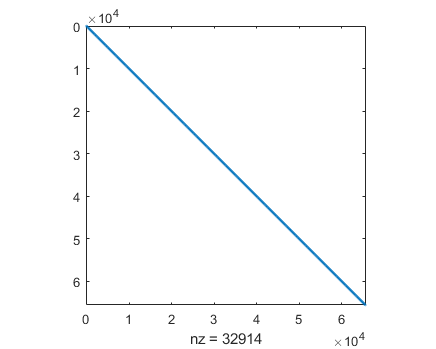

var_code = code(:);
len_code = length(var_code);
optA = spdiags(var_code, 0, len_code, len_code);
spy(optA);

density = nnz(optA)/numel(optA)

density = 7.6634e-06

sparseity = 1-density

sparseity = 1.0000

[i, j] = find(optA);
half_bandwidth = max(abs(i-j))

half_bandwidth = 0

#### 利用编码算子A对图像进行二值编码

var_mes = optA*var_im;
length(var_mes)

ans = 65536

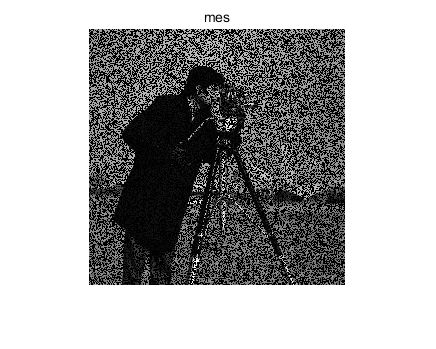

mes = reshape(var_mes, [height, width]);
imshow(mes, []);
title('mes');

psnr_mes = psnr(mes, im, 255)

psnr_mes = 8.6008

ssim_mes = ssim(mes, im)

ssim_mes = 0.0880

# ADMM滤波

利用压缩感知加入稀疏约束


$$x=\textrm{argmin}\;{\left\|\textrm{Ax}-y\right\|}_2^2 +\lambda {\left\|x\right\|}_{\textrm{TV}}$$


利用ADMM, 对问题进行分解


$$x,v,u=\textrm{argmin}\;{\left\|\textrm{Ax}-y\right\|}_2^2 +\lambda {\left\|v\right\|}_{\textrm{TV}} +u^T \left(x-v\right)+\frac{\rho }{2}{\left\|x-v\right\|}_2^2$$


可以根据KKT条件, 得到最优化的目标方程


$$\begin{array}{l}
x^{\left(t+1\right)} =\underset{x}{\textrm{argmin}} \;{\left\|\textrm{Ax}-y\right\|}_2^2 +\frac{\rho }{2}{\left\|x-\left(v^{\left(t\right)} +\frac{1}{\rho }u^{\left(t\right)} \right)\right\|}_2^2 \\
v^{\left(t+1\right)} =\underset{v}{\textrm{argmin}\;} \lambda {\left\|v\right\|}_{\textrm{TV}} +\frac{\rho }{2}{\left\|v-\left(x^{\left(t+1\right)} -\frac{1}{\rho }u^{\left(t\right)} \right)\right\|}_2^2 \\
u^{\left(t+1\right)} =u^{\left(t\right)} -\rho \left(x^{\left(t+1\right)} -v^{\left(t+1\right)} \right)
\end{array}$$


经过计算, 得到迭代公式


$$\begin{array}{l}
x^{\left(t+1\right)} ={\left(A^T A+\rho \right)}^{-1} \left({\rho v}^{\left(t\right)} +u^{\left(t\right)} +A^T y\right)\\
v^{\left(t+1\right)} ={\textrm{Denoiser}}_{\textrm{TV}} \left(x^{\left(t+1\right)} -{\frac{1}{\rho }u}^{\left(t\right)} \right)\\
u^{\left(t+1\right)} =u^{\left(t\right)} -\rho \left(x^{\left(t+1\right)} -v^{\left(t+1\right)} \right)
\end{array}$$


## 定义迭代过程的常量

A = optA;
At = optA';
spy(At);

AtA = At*A;
spy(AtA);

AtA = full(diag(AtA));
lambda = 10;
rho = 0.01;
y = var_mes;
iters_max = 64;
size_img = [height, width];
src = im;

## 定义迭代过程的变量初值

xt = 255*rand(size(src(:)));
vt = xt;
ut = 0;

## 运行迭代

fprintf('Begin ADMM algorithm restoration\n');

Begin ADMM algorithm restoration


for i=1:iters_max
    xt = (rho*vt+ut + At*y)./(AtA+rho);
    vt = TV_denoising(reshape(xt-1/rho*ut,size_img),lambda,5);
    psnr_ = psnr(vt, src, 255);
    ssim_ = ssim(vt, src);
    vt = vt(:);
    ut_ = xt-vt;
    ut = ut - rho*ut_;
    fprintf(['Iters=',num2str(i,'%02d'),'  ', ...
        'ut_=', num2str(sum(abs(ut_)),'%.4e'),'  ', ...
        'PSNR=',num2str(psnr_,'%2.4f'),'dB  ', ...
        'SSIM=',num2str(ssim_),'\n']);
    
end

Iters=01  ut_=3.3366e+05  PSNR=11.9777dB  SSIM=0.08421
Iters=02  ut_=4.2361e+04  PSNR=12.5560dB  SSIM=0.10049
Iters=03  ut_=3.3779e+04  PSNR=13.1336dB  SSIM=0.11344
Iters=04  ut_=3.2137e+04  PSNR=13.7182dB  SSIM=0.12768
Iters=05  ut_=3.1160e+04  PSNR=14.3082dB  SSIM=0.14366
Iters=06  ut_=3.0969e+04  PSNR=14.9011dB  SSIM=0.16156
Iters=07  ut_=3.0653e+04  PSNR=15.4944dB  SSIM=0.18138
Iters=08  ut_=3.0799e+04  PSNR=16.0856dB  SSIM=0.20306
Iters=09  ut_=3.0362e+04  PSNR=16.6730dB  SSIM=0.22636
Iters=10  ut_=2.9119e+04  PSNR=17.2546dB  SSIM=0.25081
Iters=11  ut_=2.7158e+04  PSNR=17.8281dB  SSIM=0.27609
Iters=12  ut_=2.5289e+04  PSNR=18.3916dB  SSIM=0.30184
Iters=13  ut_=2.3542e+04  PSNR=18.9435dB  SSIM=0.3286
Iters=14  ut_=2.1927e+04  PSNR=19.4827dB  SSIM=0.35787
Iters=15  ut_=2.0664e+04  PSNR=20.0072dB  SSIM=0.38844
Iters=16  ut_=1.9551e+04  PSNR=20.5159dB  SSIM=0.42002
Iters=17  ut_=1.8234e+04  PSNR=21.0087dB  SSIM=0.45166
Iters=18  ut_=1.6480e+04  PSNR=21.4851dB  SSIM=0.48373
Iters=19  u

## 对比结果

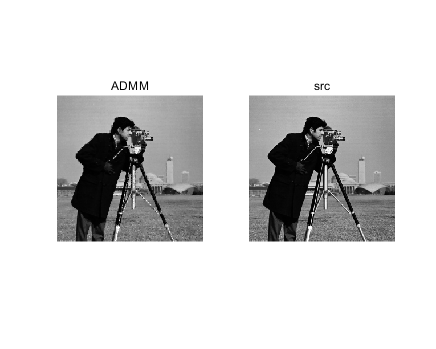

subplot(1,2,1);
imshow(reshape(xt,size_img),[]); title('ADMM');
subplot(1,2,2);
imshow(src,[]); title('src');

fprintf(['Iters=',num2str(i,'%02d'),'  ', ...
    'PSNR=',num2str(psnr_),'dB  ', ...
    'SSIM=',num2str(ssim_),'\n']);

Iters=64  PSNR=26.8325dB  SSIM=0.77138


# GAP滤波 

利用压缩感知加入稀疏约束


$$x=\textrm{argmin}\;{\left\|\textrm{Ax}-y\right\|}_2^2 +\lambda {\left\|x\right\|}_{\textrm{TV}}$$


利用ADMM, 对问题进行分解


$$x,v=\textrm{argmin}\;{\left\|\textrm{Ax}-y\right\|}_2^2 +\lambda {\left\|v\right\|}_{\textrm{TV}}$$


可以根据KKT条件, 得到最优化的迭代公式


$$\begin{array}{l}
x^{\left(t+1\right)} =v^{\left(t\right)} +\Delta {\left(A^T A\right)}^{-1} A^T \left(\;y-Av^{\left(t\right)} \right)\\
v^{\left(t+1\right)} ={\textrm{Denoiser}}_{\textrm{TV}} \left(x^{\left(t+1\right)} \right)
\end{array}$$


## 定义迭代过程的常量

A = optA;
At = optA';
spy(At);
AtA = At*A;
spy(AtA);
AtA = full(diag(AtA));
lambda = 10;
delta = 1;
y = var_mes;
iters_max = 64;
size_img = [height, width];
src = im;

## 定义迭代过程的变量初值

xt = 255*rand(size(src(:)));
vt = xt;

## 运行迭代

fprintf('Begin GAP algorithm restoration\n');

Begin GAP algorithm restoration


for i=1:iters_max
    xt = vt + delta*At*(y-A*vt)./(AtA+eps);
    vt = TV_denoising(reshape(xt,size_img),lambda,5);
    psnr_ = psnr(vt, src, 255);
    ssim_ = ssim(vt, src);
    vt = vt(:);
    fprintf(['Iters=',num2str(i,'%02d'),'  ', ...
        'PSNR=',num2str(psnr_,'%2.4f'),'dB  ', ...
        'SSIM=',num2str(ssim_),'\n']);
end

Iters=01  PSNR=11.9916dB  SSIM=0.081361
Iters=02  PSNR=12.5602dB  SSIM=0.09154
Iters=03  PSNR=13.1386dB  SSIM=0.103
Iters=04  PSNR=13.7252dB  SSIM=0.11591
Iters=05  PSNR=14.3178dB  SSIM=0.13039
Iters=06  PSNR=14.9140dB  SSIM=0.14659
Iters=07  PSNR=15.5112dB  SSIM=0.16451
Iters=08  PSNR=16.1067dB  SSIM=0.18389
Iters=09  PSNR=16.6979dB  SSIM=0.2043
Iters=10  PSNR=17.2828dB  SSIM=0.22516
Iters=11  PSNR=17.8593dB  SSIM=0.24595
Iters=12  PSNR=18.4254dB  SSIM=0.26647
Iters=13  PSNR=18.9789dB  SSIM=0.28707
Iters=14  PSNR=19.5179dB  SSIM=0.3079
Iters=15  PSNR=20.0414dB  SSIM=0.32922
Iters=16  PSNR=20.5482dB  SSIM=0.3498
Iters=17  PSNR=21.0378dB  SSIM=0.37015
Iters=18  PSNR=21.5092dB  SSIM=0.39044
Iters=19  PSNR=21.9618dB  SSIM=0.41046
Iters=20  PSNR=22.3946dB  SSIM=0.42997
Iters=21  PSNR=22.8059dB  SSIM=0.44768
Iters=22  PSNR=23.1942dB  SSIM=0.46338
Iters=23  PSNR=23.5585dB  SSIM=0.47654
Iters=24  PSNR=23.8981dB  SSIM=0.48769
Iters=25  PSNR=24.2130dB  SSIM=0.49738
Iters=26  PSNR=24.5028dB  SSI

## 对比结果

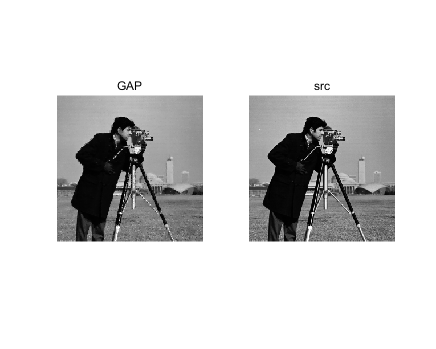

subplot(1,2,1);
imshow(reshape(xt,size_img),[]); title('GAP');
subplot(1,2,2);
imshow(src,[]); title('src');

fprintf(['Iters=',num2str(i,'%02d'),'  ', ...
    'PSNR=',num2str(psnr_),'dB  ', ...
    'SSIM=',num2str(ssim_),'\n']);

Iters=64  PSNR=26.588dB  SSIM=0.61064
